# 'surface' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);


#### Scene 1

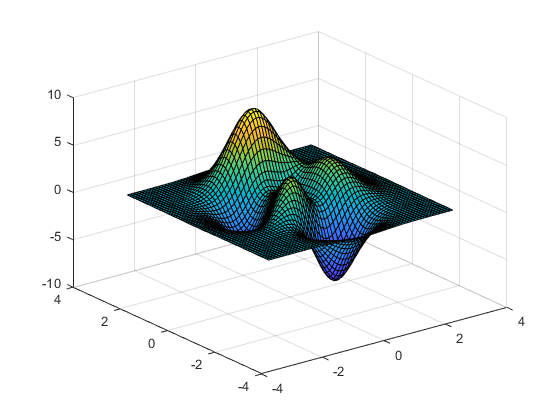


pl.scene_begin('scene_file', 'surface1.pov', 'image_file', 'surface1.png');
    pl.include("glass");
    pl.include("metals");
       
    % Camera
    pl.camera('angle', 35, 'location', [-10 -10 6], 'look_at', [0 0 0], 'type', 'perspective');

    % Lights
    pl.light('location', [-10 -17 7],   'color', [2 2 2], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);

    % Axis
    % tex_gray   = pl.declare("tex_gray",   pl.texture('pigment', [0.2 0.2 0.2]));
    % tex_yellow = pl.declare("tex_yellow", pl.texture('pigment', [0.6 0.6 0.0]));
    % pl.axis('length', [5 5 3], 'radius', 0.03, 'tex_common', tex_gray, 'tex_x', tex_yellow, 'tex_y', tex_yellow, 'tex_z', tex_yellow);
    
    % Hide preview
    %f = figure('Visible', 'off');
    %ax = axes(f);

    % Surface
    size = 60;
    [X,Y,Z] = peaks(size);
    s = surf(X,Y,Z);

    % With checkerd texture
    pl.surface('surface', s, 'scale', [1, 1, 0.35], 'texture_odd', 'Gold_Nugget', 'texture_even', 'T_Ruby_Glass');

    % With color map
    %finish = pl.declare("f", "finish {ambient 0.01 diffuse 0.3 reflection 0.1 specular 5.4 roughness 0.4}");
    %pl.surface('surface', s, 'colormap', 'jet', 'scale', [1, 1, 0.35], 'finish', finish);
pl.scene_end();
 

#### Render and display

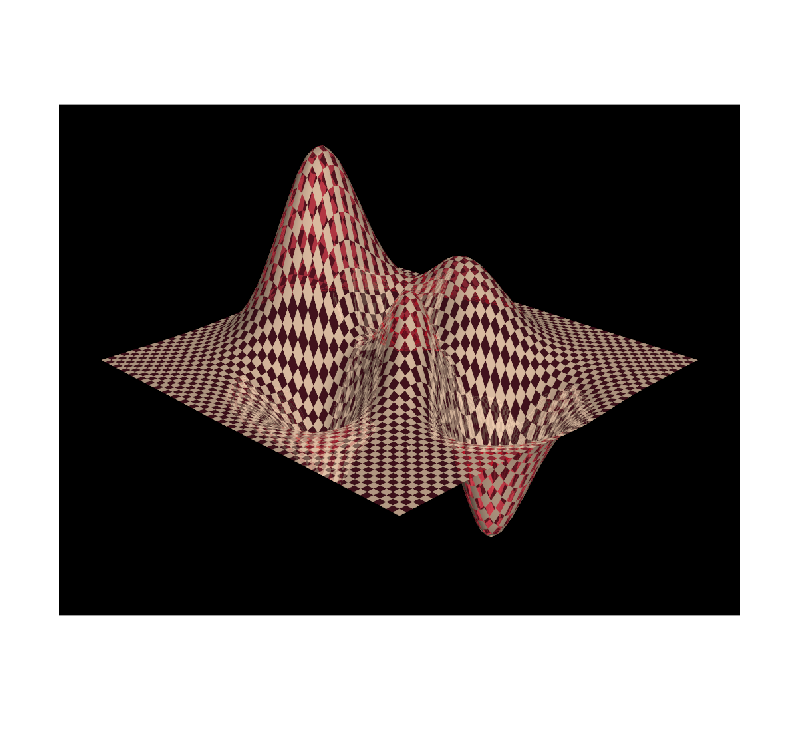

figure()
image = pl.render();
imshow(image);

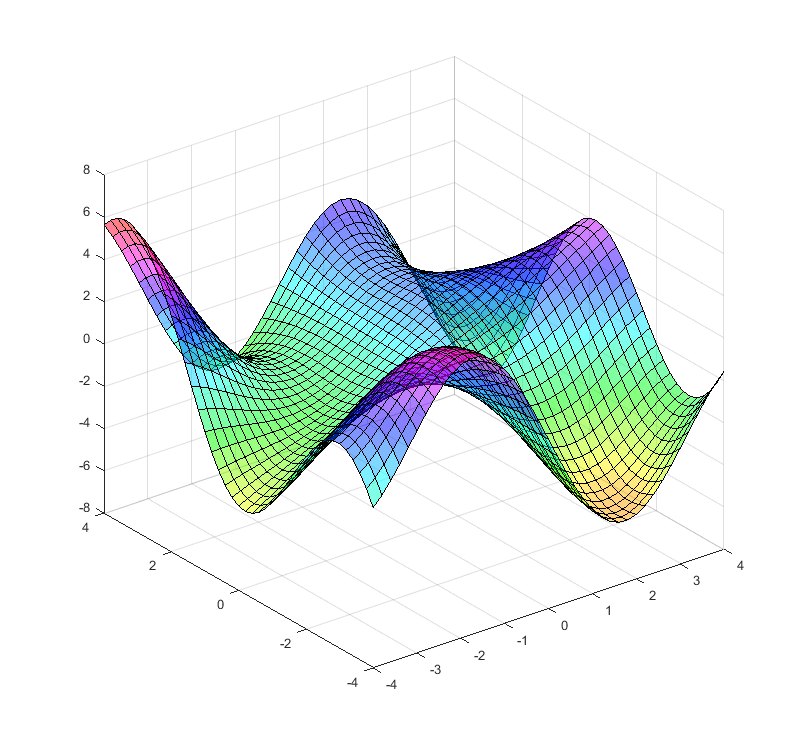


% Scene 2
pl.scene_begin('scene_file', 'surface2.pov', 'image_file', 'surface2.png');
    pl.include("glass");
    pl.include("metals");

    % Camera
    pl.camera('angle', 35, 'location', [-13 -13 8], 'look_at', [0 0.2 0], 'type', 'perspective');

    % Lights
    pl.light('location', [-10 -17 7],   'color', [2.5 2.5 2.5], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1],       'shadowless', true);

    % Axis
    % tex_gray   = pl.declare("tex_gray",   pl.texture('pigment', [0.2 0.2 0.2]));
    % tex_yellow = pl.declare("tex_yellow", pl.texture('pigment', [0.6 0.6 0.0]));
    % pl.axis('length', [5 5 3], 'radius', 0.03, 'tex_common', tex_gray, 'tex_x', tex_yellow, 'tex_y', tex_yellow, 'tex_z', tex_yellow);
    
    % Hide preview
    % f = figure('Visible', 'off');
    % ax = axes(f);

    % Surface
    [X,Y] = meshgrid(-4:.2:4);
    Z = Y.*sin(X) + X.*cos(Y);
    s = surf(X,Y,Z,'FaceAlpha',0.5);

    % With checkerd texture
    % pl.surface('surface', s, 'scale', [1, 1, 0.35], 'texture_odd', 'Bright_Bronze', 'texture_even', 'Orange_Glass');
    % With color map
    finish = pl.declare("f", "finish {ambient 0.01 diffuse 0.3 reflection 0.1 specular 5.4 roughness 0.4}");
    pl.surface('surface', s, 'colormap', 'hsv', 'scale', [1, 1, 0.35], 'finish', finish);

pl.scene_end();

#### Render and display

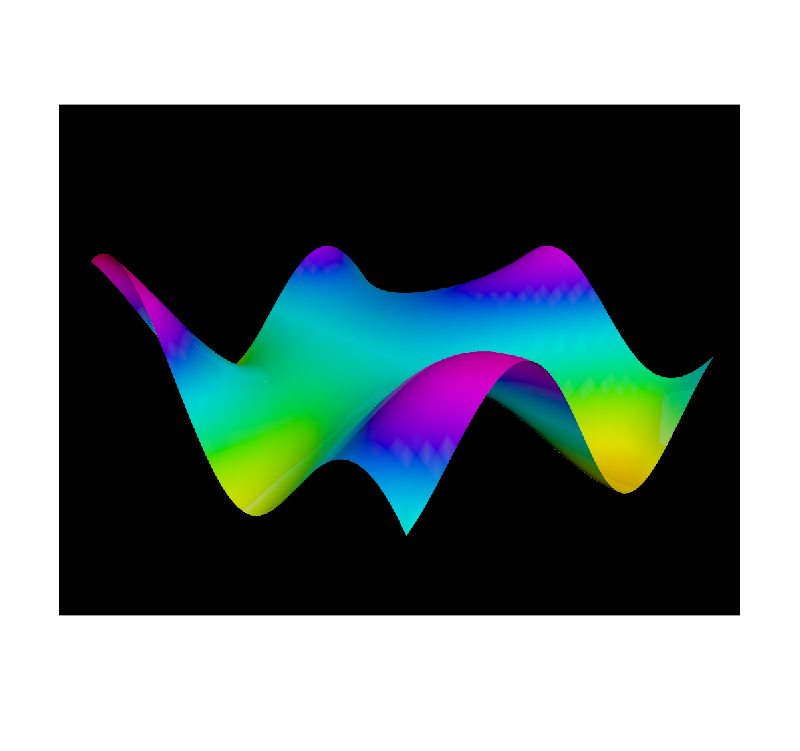

figure();
image = pl.render();
imshow(image);

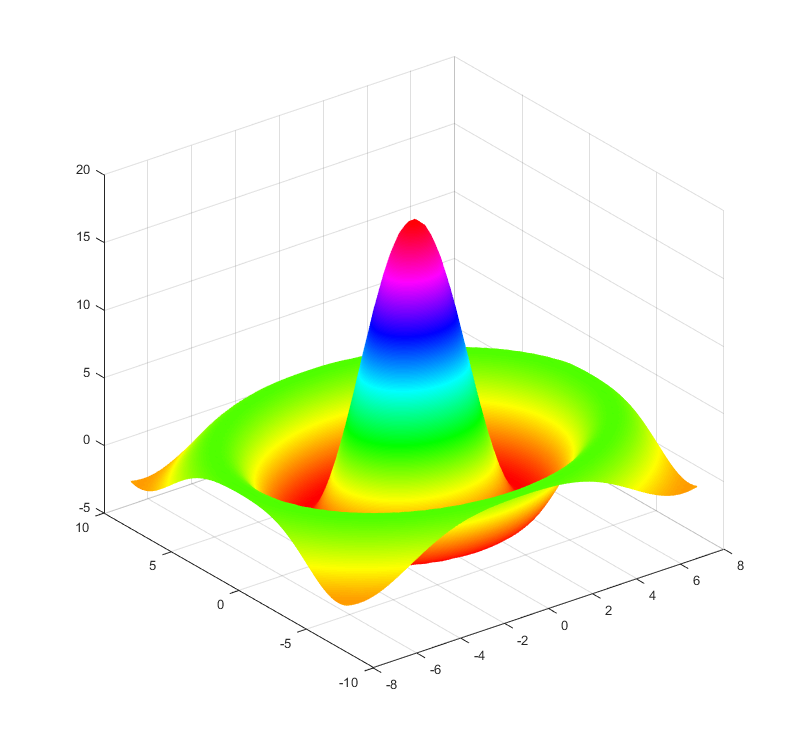


% Scene 3
pl.scene_begin('scene_file', 'surface3.pov', 'image_file', 'surface3.png');
    pl.include("glass");
    pl.include("metals");

    % Camera
    pl.camera('angle', 35, 'location', [-25 -25 24], 'look_at', [0 0 0.5], 'type', 'perspective');

    % Lights
    pl.light('location', [-10 -17 7],   'color', [2.5 2.5 2.5], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1],       'shadowless', true);

    % Axis
    % tex_gray   = pl.declare("tex_gray",   pl.texture('pigment', [0.2 0.2 0.2]));
    % tex_yellow = pl.declare("tex_yellow", pl.texture('pigment', [0.6 0.6 0.0]));
    % pl.axis('length', [5 5 3], 'radius', 0.03, 'tex_common', tex_gray, 'tex_x', tex_yellow, 'tex_y', tex_yellow, 'tex_z', tex_yellow);
    
    % Hide preview
    %f = figure('Visible', 'off');
    %ax = axes(f);
    
    % Surface
    t = linspace (-8, 8, 60);
    [x, y] = meshgrid (t, t);
    r = sqrt (x .^ 2 + y .^ 2) + eps;
    z = 18 * sin (r) ./ r;
    s = surf(x,y,z, FaceColor = 'interp', EdgeColor = 'interp');
    
    % With checkerd texture
    % pl.surface('surface', s, 'scale', [1, 1, 0.4], 'texture_odd', 'Aluminum', 'texture_even', 'T_Winebottle_Glass');
    
    % With flat texture
    % pl.surface('surface', s, 'scale', [1, 1, 0.4], 'texture', 'Aluminum');
    % pl.surface('surface', s, 'scale', [1, 1, 0.4], 'texture', 'T_Winebottle_Glass');
    
    % With color map
    finish = pl.declare("f", "finish {ambient 0.01 diffuse 0.3 reflection 0.1 specular 5.4 roughness 0.4}");
    pl.surface('surface', s, 'colormap', 'hsv', 'scale', [1, 1, 0.4], 'finish', finish);

pl.scene_end();

#### Render and display

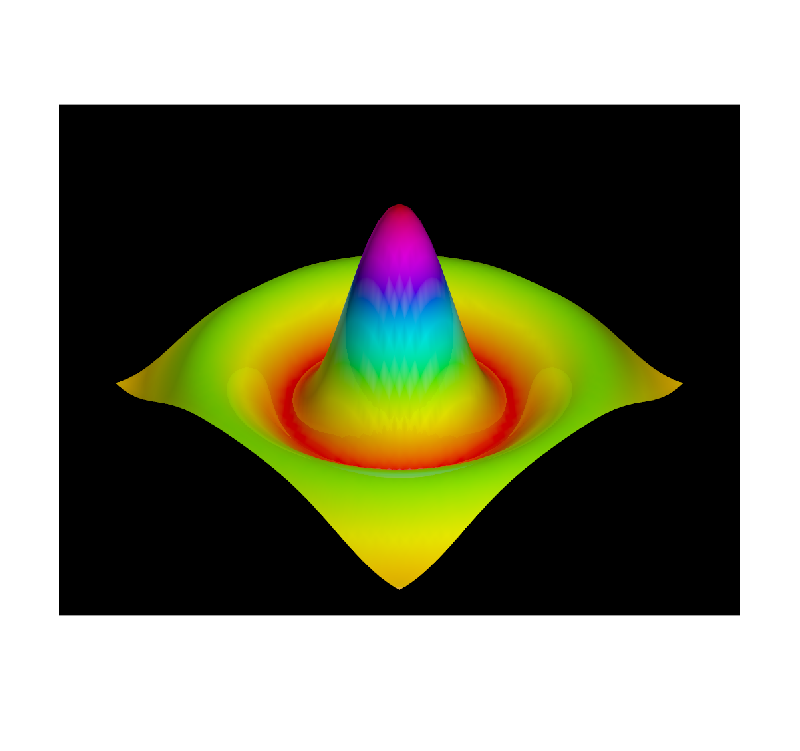

figure();
image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 34.697963 seconds.
